# Práctica 1. Medida del caudal

## Datos

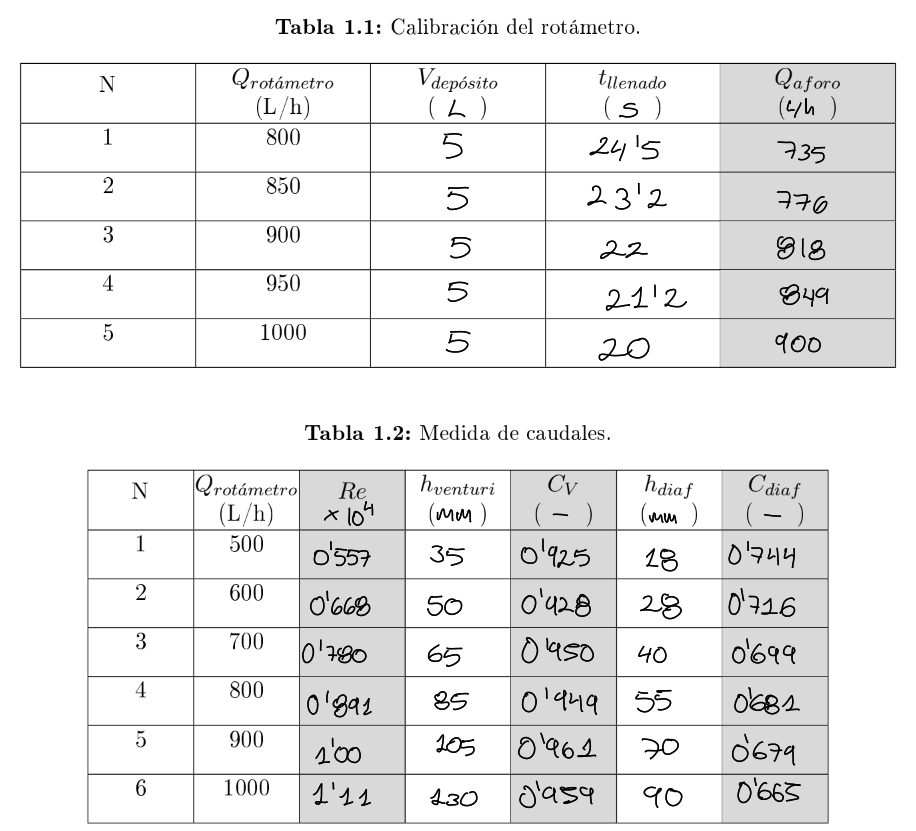

**Calibración del rotámetro**

Q_rot1=[800 850 900 950 1000]; %[L/h] caudal del rotámetro 
V_dep=[5 5 5 5 5]; %[L] volumen del depósito 
t_ll=[24.5 23.2 22 21.2 20]; %[s] tiempo de llenado del volumen definido

**Medida  de caudales**

Q_rot2=[500 600 700 800 900 1000]; %[L/h] caudal del rotámetro 
h_vent=[35 50 65 85 105 130]; %[mm] diferencia de alturas
h_diaf=[18 28 40 55 70 90]; %[mm] diferencia de alturas

**Cálculos y datos**

%Cálculo del aforo directo en la calibración del rotámetro
Q_aforo=(V_dep./t_ll).*3600; %[L/h] caudal estimado de acuerdo al volumen 
% del depósito y tiempo de llenado medidos

%error cometido
ERROR=abs((Q_rot1-Q_aforo)./Q_rot1)*100 %Error de caudal

ERROR =     8.1633    8.7221    9.0909   10.6256   10.0000


%Datos 
D_vent1=0.03175; %[m] diámetro mayor del conducto
D_vent2=0.015; %[m] diámetro del estrechamiento del venturímetro 

D_diaf1=0.03175; %[m] diámetro mayor del conducto
D_diaf0=0.020; %[m] diámetro de la vena contraída del diafragma 

beta=D_vent2/D_vent1; %[-] 
g=9.81; %[m/s^2] aceleración gravitatoria
Q_rot2SI=Q_rot2.*((10^-3)./3600); %[m^3/s] caudal en SI
mu=10^-3; %[Pa*s] viscosidad absoluta del agua
rho=1000; %[kg/m^3] densidad del agua

**Cálculo del coeficiente de velocidad, diafragma y el número de Reynolds**


$$C_V =\frac{4Q}{\pi D_2^2 }\sqrt{\frac{1-\beta^4 }{2g\Delta h}}\;\;\;\;,\;\;\;\;C=\frac{4Q}{\pi D_0^2 \sqrt{2g\Delta h}}\;\;\;\;,\;\;\;\textrm{Re}=\frac{4\rho Q}{\pi \mu D_1 }\;\;,\;\;\;\beta =\frac{D_2 }{D_1 }$$


C_v=zeros(1,6);
C=zeros(1,6);
Re=zeros(1,6);
for i=1:1:6
C_v(i)=(4*Q_rot2SI(i)./(pi*(D_vent2^2)))*sqrt((1-(beta.^4))./(2*g*h_vent(i)*(10^-3)));
C(i)=(4*Q_rot2SI(i))./(pi*D_diaf0^2*sqrt(2*g*h_diaf(i)*(10^-3)));
Re(i)=(4*rho*Q_rot2SI(i))./(pi().*mu.*D_vent1);
end
C_v

C_v =     0.9245    0.9282    0.9498    0.9492    0.9608    0.9594


C

C =     0.7439    0.7158    0.6987    0.6809    0.6790    0.6654


Re

Re = 1.0e+04 *

    0.5570    0.6684    0.7798    0.8912    1.0026    1.1139


**Gráfico venturímetro y del diafragma**

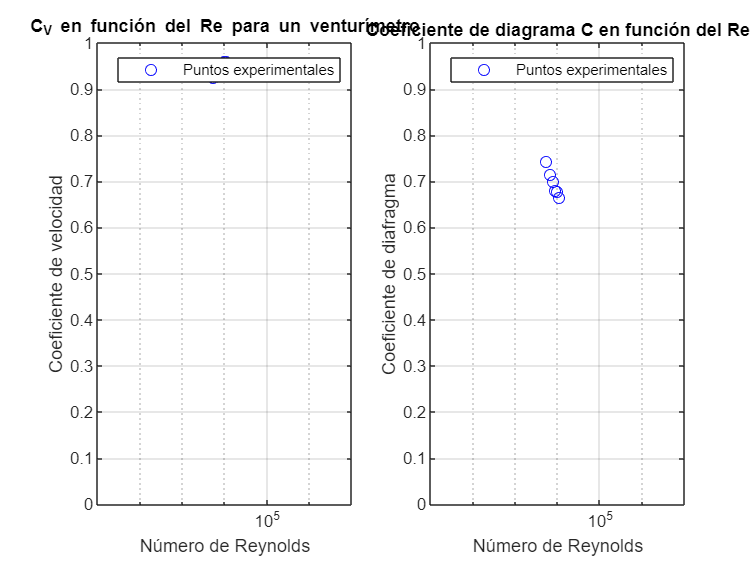

figure(1)
subplot(1,2,1)
semilogx(Re,C_v,'o','Color','blue')
xlabel('Número de Reynolds')
ylabel('Coeficiente de velocidad')
title('C_V en función del Re para un venturímetro')
xlim([10 10000000])
ylim([0 1])
legend('Puntos experimentales')
grid on

subplot(1,2,2)
semilogx(Re,C,'o','Color','blue')
xlabel('Número de Reynolds')
ylabel('Coeficiente de diafragma')
title('Coeficiente de diagrama C en función del Re')
xlim([10 10000000])
ylim([0 1])
legend('Puntos experimentales')
grid on

**Gráficos de Re-Cv y Re-C**

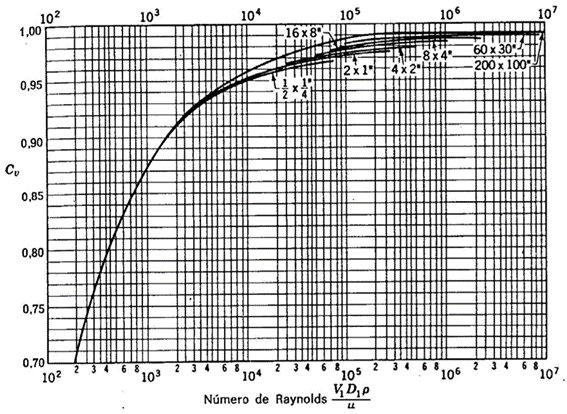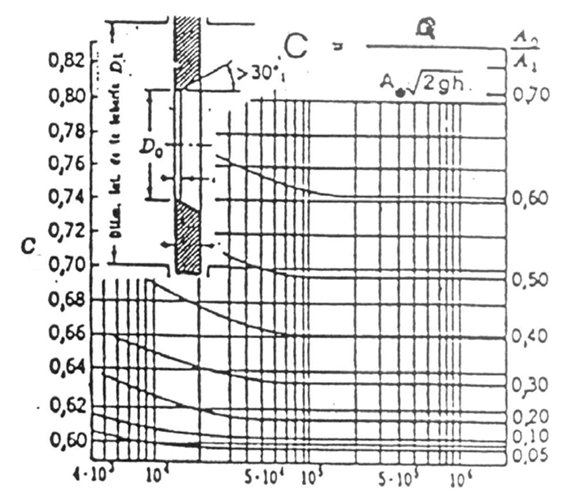

# Práctica 2. Medida de la velocidad

## **Datos**

## 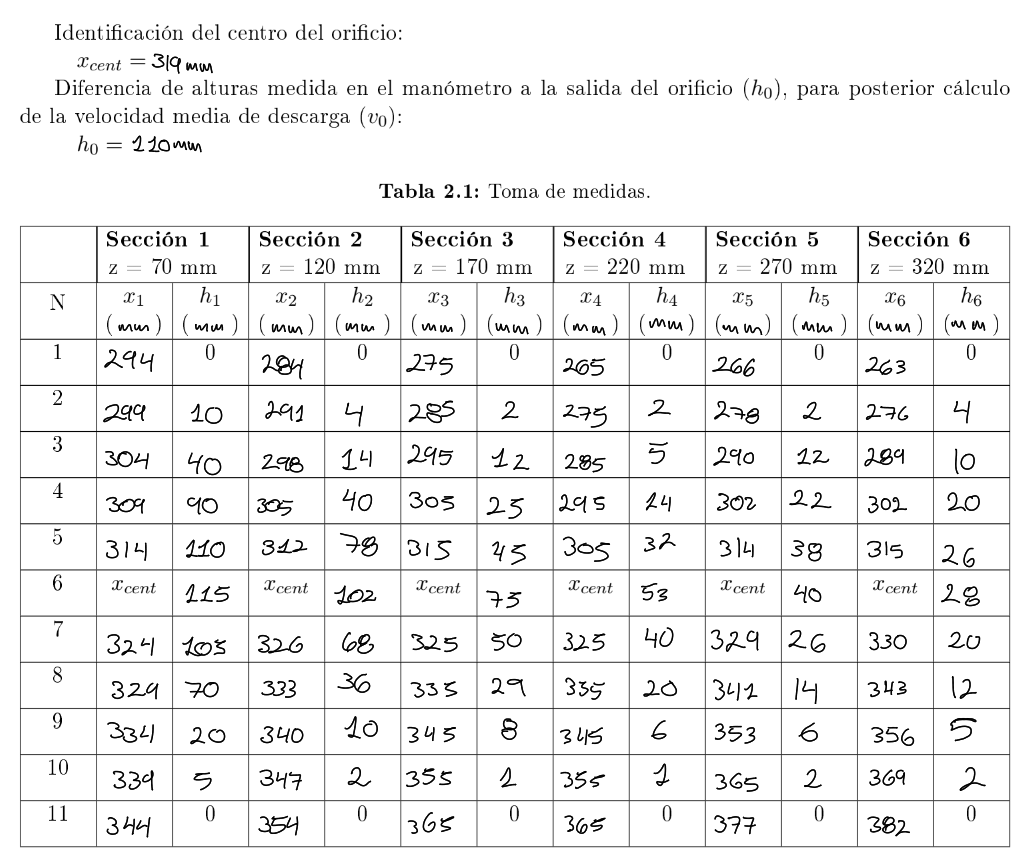

**Velocidad media de descarga**


$$v=\sqrt{\frac{2\rho_k \textrm{gh}}{\rho }}$$


x0=319*10^-3;%[m] posición central del pitot
h0=110*((10^-3)/2);%[m] diferencia de alturas manométrica
rho_k=800;%[kg/m^3] densidad del queroseno
rho=1;%[kg/m^3] densidad del aire
g=9.81;%[m/s^2] aceleración de la gravedad
R_C0=15*(10^-3)%[m] radio del orificio de descarga

R_C0 = 0.0150

v_00=sqrt((2*rho_k*g*h0)/(rho))% [m/s] velocidad local del centro del chorro z=0 m

v_00 = 29.3816

**Sección 1**

z1=70*10^-3;%[m
x1=[294 299 304 309 314 319 324 329 334 339 344].*10^-3;%[m]
h1=[0 10 40 90 110 115 105 70 20 5 0].*((10^-3)/2);%[m]
R_C1=(abs(x0-x1(1))+abs(x0-x1(11)))/2%[m] radio medio de la sección

R_C1 = 0.0250

v_1=sqrt((2.*rho_k.*g.*h1)/(rho));% [m/s] perfil de velocidades
v_01=max(v_1)% [m/s] velocidad local del centro del chorro

v_01 = 30.0420

**Sección 2**

z2=120*10^-3;%[m]
x2=[284 291 298 305 312 319 326 333 340 347 354].*10^-3;%[m]
h2=[0 4 14 40 78 102 68 36 10 2 0].*((10^-3)/2);%[m]
R_C2=(abs(x0-x2(1))+abs(x0-x2(11)))/2%[m] radio medio de la sección

R_C2 = 0.0350

v_2=sqrt((2.*rho_k.*g.*h2)/(rho));% [m/s] perfil de velocidades
v_02=max(v_2)% [m/s] velocidad local del centro del chorro

v_02 = 28.2930

**Sección 3**

z3=170*10^-3;%[m]
x3=[275 285 295 305 315 319 325 335 345 355 365].*10^-3;%[m]
h3=[0 2 12 25 45 75 50 29 8 1 0].*((10^-3)/2);%[m]
R_C3=(abs(x0-x3(1))+abs(x0-x3(11)))/2%[m] radio medio de la sección

R_C3 = 0.0450

v_3=sqrt((2.*rho_k.*g.*h3)/(rho));% [m/s] perfil de velocidades
v_03=max(v_3)% [m/s] velocidad local del centro del chorro

v_03 = 24.2611

**Sección 4**

z4=220*10^-3;%[m]
x4=[265 275 285 295 305 319 325 335 345 355 365].*10^-3;%[m]
h4=[0 2 5 14 32 53 40 20 6 1 0].*((10^-3)/2);%[m]
R_C4=(abs(x0-x4(1))+abs(x4(11)-x0))/2%[m] radio medio de la sección

R_C4 = 0.0500

v_4=sqrt((2.*rho_k.*g.*h4)/(rho));% [m/s] perfil de velocidades
v_04=max(v_4)% [m/s] velocidad local del centro del chorro

v_04 = 20.3947

**Sección 5**

z5=270*10^-3;%[m]
x5=[266 278 290 302 314 319 329 341 353 365 377].*10^-3;%[m]
h5=[0 2 12 22 38 40 26 14 6 2 0].*((10^-3)/2);%[m]
R_C5=(abs(x0-x5(1))+abs(x0-x5(11)))/2%[m] radio medio de la sección

R_C5 = 0.0555

v_5=sqrt((2.*rho_k.*g.*h5)/(rho));% [m/s] perfil de velocidades
v_05=max(v_5)% [m/s] velocidad local del centro del chorro

v_05 = 17.7178

**Sección 6**

z6=320*10^-3;%[m]
x6=[263 276 289 302 315 319 330 343 356 369 382].*10^-3;%[m]
h6=[0 4 10 20 26 28 20 12 5 2 0].*((10^-3)/2);%[m]
R_C6=(abs(x0-x6(1))+abs(x0-x6(11)))/2%[m] radio medio de la sección

R_C6 = 0.0595

v_6=sqrt((2.*rho_k.*g.*h6)/(rho));% [m/s] perfil de velocidades
v_06=max(v_6)% [m/s] velocidad local del centro del chorro

v_06 = 14.8238

**Disminución de la velocidad local del centro del chorro por sección**

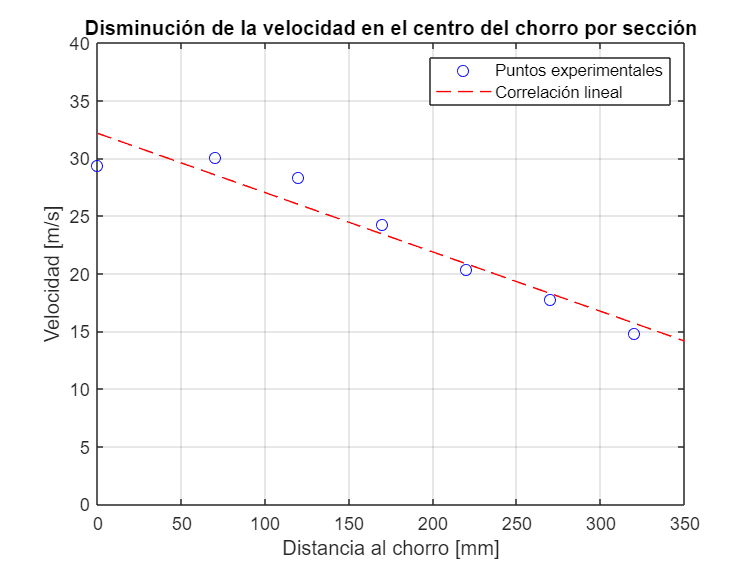

Z=[0 z1 z2 z3 z4 z5 z6].*1000; %[mm] distancias al chorro de cada sección
V=[v_00 v_01 v_02 v_03 v_04 v_05 v_06];%[m/s] velocidades al centro del chorro
% de cada sección
figure(2)
plot(Z,V,'o','color','blue')
xlabel('Distancia al chorro [mm]')
ylabel('Velocidad [m/s]')
title('Disminución de la velocidad en el centro del chorro por sección')
xlim([0 350])
ylim([0 40])
l=polyfit(Z,V,1);%interpolación lineal 
L=poly2sym(l);
hold on
fplot(L,'--','color','red')
hold off
legend('Puntos experimentales','Correlación lineal')
grid on

**Perfil de velocidades de la sección 1**


$$v\left(r,R_c \right)=v_c {\left(1-{\left(\frac{r}{R_c }\right)}^2 \right)}^2$$


figure(3)
subplot(2,3,1);
x01=(x1-x0).*1000; %[mm] distancia de cada punto al centro del chorro
F1=@(x) v_01.*(1-(x./(R_C1.*1000)).^2).^2; %[m/S] curva teórica de velocidad
plot(x01,v_1,'o','color','blue')
xlabel('Eje X. El origen es el centro del chorro [mm]')
ylabel('Velocidad [m/s]')
title('Perfil de velocidades de la sección 1')
p1=polyfit(x01,v_1,4); %interpolación polinómica experimental
P1=poly2sym(p1);
hold on
fplot(P1,'--','color','red')
fplot(F1,'color','black')
hold off
legend('Puntos experimentales','Perfil experimental','Curva teórica')
ylim([0 40])
xlim([-28 28.5])
grid on

**Perfil de velocidades de la sección 2**

subplot(2,3,2);
x02=(x2-x0).*1000;%[mm] distancia de cada punto al centro del chorro
F2=@(x) v_02.*(1-(x./(R_C2.*1000)).^2).^2;%[m/S] curva teórica de velocidad
plot(x02,v_2,'o','color','blue')
xlabel('Eje X. El origen es el centro del chorro [mm]')
ylabel('Velocidad [m/s]')
title('Perfil de velocidades de la sección 2')
p2=polyfit(x02,v_2,4);%interpolación polinómica experimental
P2=poly2sym(p2);
hold on
fplot(P2,'--','color','red')
fplot(F2,'color','black')
hold off
legend('Puntos experimentales','Perfil experimental','Curva teórica')
xlim([-39 38.5])
ylim([0 38])
grid on

**Perfil de velocidades de la sección 3**

subplot(2,3,3);
x03=(x3-x0).*1000;%[mm] distancia de cada punto al centro del chorro
F3=@(x) v_03.*(1-(x./(R_C3.*1000)).^2).^2;%[m/S] curva teórica de velocidad
plot(x03,v_3,'o','color','blue')
xlabel('Eje X. El origen es el centro del chorro [mm]')
ylabel('Velocidad [m/s]')
title('Perfil de velocidades de la sección 3')
p3=polyfit(x03,v_3,4);%interpolación polinómica experimental
P3=poly2sym(p3);
hold on
fplot(P3,'--','color','red')
fplot(F3,'color','black')
hold off
legend('Puntos experimentales','Perfil experimental','Curva teórica')
ylim([0 34])
xlim([-47.4 49.5])
grid on

**Perfil de velocidades de la sección 4**

subplot(2,3,4);
x04=(x4-x0).*1000;%[mm] distancia de cada punto al centro del chorro
F4=@(x) v_04.*(1-(x./(R_C4.*1000)).^2).^2;%[m/S] curva teórica de velocidad 
plot(x04,v_4,'o','color','blue')
xlabel('Eje X. El origen es el centro del chorro [mm]')
ylabel('Velocidad [m/s]')
title('Perfil de velocidades de la sección 4')
p4=polyfit(x04,v_4,4);%interpolación polinómica experimental
P4=poly2sym(p4);
hold on
fplot(P4,'--','color','red')
fplot(F4,'color','black')
hold off
legend('Puntos experimentales','Perfil experimental','Curva teórica')
ylim([0 30])
xlim([-57.5 50])
grid on

**Perfil de velocidades de la sección 5**

subplot(2,3,5);
x05=(x5-x0).*1000;%[mm] distancia de cada punto al centro del chorro
F5=@(x) v_05.*(1-(x./(R_C5.*1000)).^2).^2;%[m/S] curva teórica de velocidad
plot(x05,v_5,'o','color','blue')
xlabel('Eje X. El origen es el centro del chorro [mm]')
ylabel('Velocidad [m/s]')
title('Perfil de velocidades de la sección 5')
p5=polyfit(x05,v_5,4);%interpolación polinómica experimental
P5=poly2sym(p5);
hold on
fplot(P5,'--','color','red')
fplot(F5,'color','black')
hold off
legend('Puntos experimentales','Perfil experimental','Curva teórica')
ylim([0 25])
xlim([-56.6 61])
grid on

**Perfil de velocidades de la sección 6**

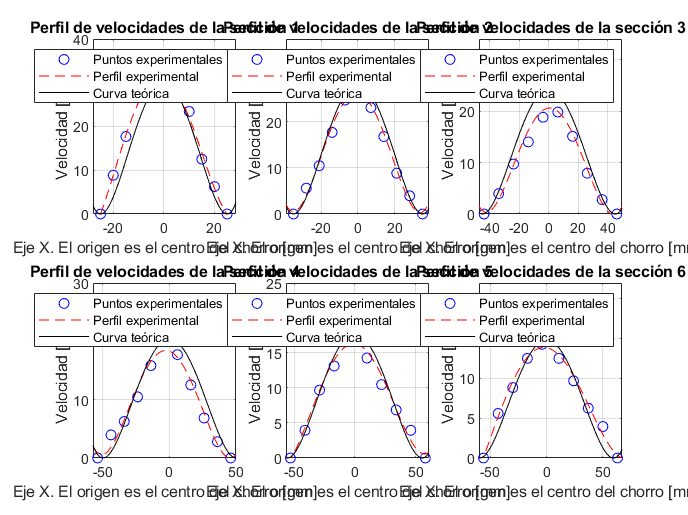

subplot(2,3,6)
x06=(x6-x0).*1000;%[mm] distancia de cada punto al centro del chorro
F6=@(x) v_06.*(1-(x./(R_C6.*1000)).^2).^2;%[m/S] curva teórica de velocidad
plot(x06,v_6,'o','color','blue')
xlabel('Eje X. El origen es el centro del chorro [mm]')
ylabel('Velocidad [m/s]')
title('Perfil de velocidades de la sección 6')
p6=polyfit(x06,v_6,4);%interpolación polinómica experimental
P6=poly2sym(p6);
hold on
fplot(P6,'--','color','red')
fplot(F6,'color','black')
hold off
legend('Puntos experimentales','Perfil experimental','Curva teórica')
ylim([0 22])
xlim([-60 67])
grid on

**Evolución del perfil experimental y el teórico con la sección **

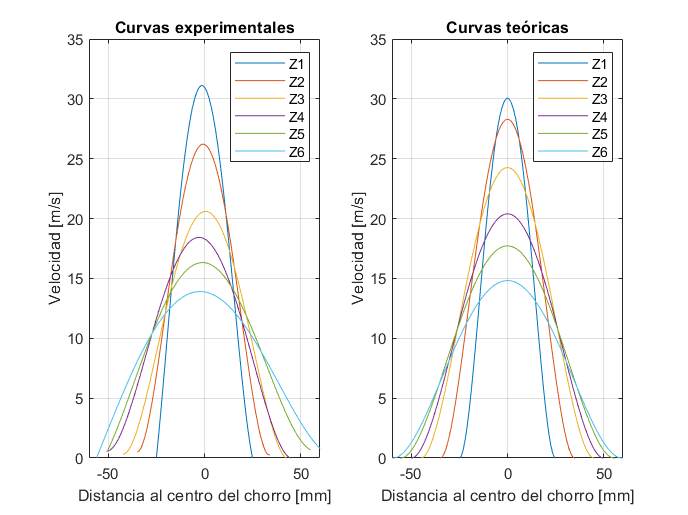

figure(8)
subplot(1,2,1)
fplot(P1,[-25,25])
hold on
fplot(P2,[-35,34])
fplot(P3,[-42.4, 42.4])
fplot(P4,[-51,45.5])
fplot(P5,[-50.5,55])
fplot(P6,[-56,65])
hold off
grid on
xlabel('Distancia al centro del chorro [mm]')
ylabel('Velocidad [m/s]')
title('Curvas experimentales')
legend('Z1','Z2','Z3','Z4','Z5','Z6')
ylim([0 35])
xlim([-60 60])

subplot(1,2,2)
fplot(F1,[-25,25])
hold on
fplot(F2,[-35,35])
fplot(F3,[-45,45])
fplot(F4,[-50,50])
fplot(F5,[-55.8,55.8])
fplot(F6,[-60,60])
hold off
grid on
xlabel('Distancia al centro del chorro [mm]')
ylabel('Velocidad [m/s]')
title('Curvas teóricas')
legend('Z1','Z2','Z3','Z4','Z5','Z6')
ylim([0 35])
xlim([-60 60])

**Cálculo del gasto másico**


$$G=\rho \int_0^{R_c } 2\pi \textrm{rv}\left(r\right)\;\textrm{dr}=\rho \frac{\pi }{3}v_c R_c^2$$


syms x

F00=@(x) x.*rho.*2.*pi().*v_00.*((1-(x./(R_C0)).^2).^2) ;
rho*(pi()/3)*v_01*R_C1^2

ans = 0.0197

G0=integral(F00,0,R_C0)*1000 %[g/s]gasto másico de la sección 0

G0 = 6.9229


F11=@(x) x.*rho.*2.*pi().*v_01.*((1-(x./(R_C1)).^2).^2);
G1=integral(F11,0,R_C1)*1000 %[g/s]gasto másico de la sección 1

G1 = 19.6624


F22=@(x) x.*rho.*2.*pi().*v_02.*((1-(x./(R_C2)).^2).^2);
G2=integral(F22,0,R_C2)*1000 %[g/s]gasto másico de la sección 2

G2 = 36.2948


F33=@(x) x.*rho.*2.*pi().*v_03.*((1-(x./(R_C3)).^2).^2);
G3=integral(F33,0,R_C3)*1000 %[g/s]gasto másico de la sección 3

G3 = 51.4474


F44=@(x) x.*rho.*2.*pi().*v_04.*((1-(x./(R_C4)).^2).^2);
G4=integral(F44,0,R_C4)*1000 %[g/s]gasto másico de la sección 4

G4 = 53.3932


F55=@(x) x.*rho.*2.*pi().*v_05.*((1-(x./(R_C5)).^2).^2);
G5=integral(F55,0,R_C5)*1000 %[g/s]gasto másico de la sección 5

G5 = 57.1510


F66=@(x) x.*rho.*2.*pi().*v_06.*((1-(x./(R_C6)).^2).^2);
G6=integral(F66,0,R_C6)*1000 %[g/s]gasto másico de la sección 6

G6 = 54.9568

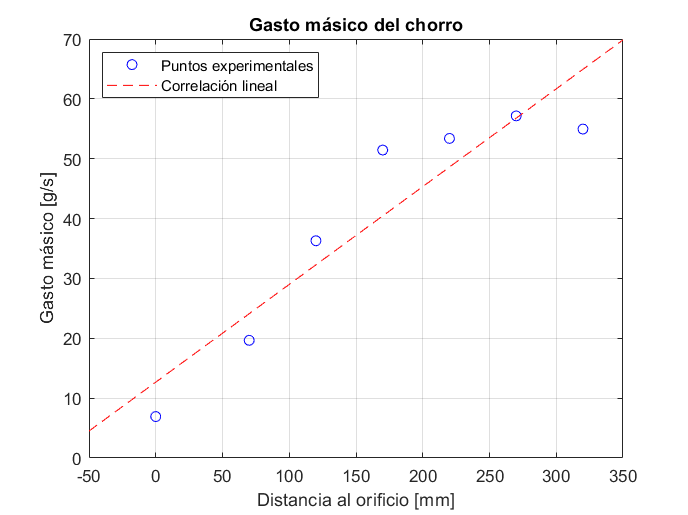


G=[G0 G1 G2 G3 G4 G5 G6];%Vector de gasto másico

figure(4)
plot(Z,G,'o','color','blue')

pp=polyfit(Z,G,1);
PP=poly2sym(pp);
hold on
fplot(PP,'--','color','red')
title('Gasto másico del chorro')
xlabel('Distancia al orificio [mm]')
ylabel('Gasto másico [g/s]')
legend('Puntos experimentales','Correlación lineal','Location','northwest')
hold off
grid on

**Gasto másico del fluido exterior**

Gfe=[G1-G0 G2-G1 G3-G2 G4-G3 G5-G4 G6-G5]

Gfe =    12.7395   16.6324   15.1527    1.9458    3.7578   -2.1943


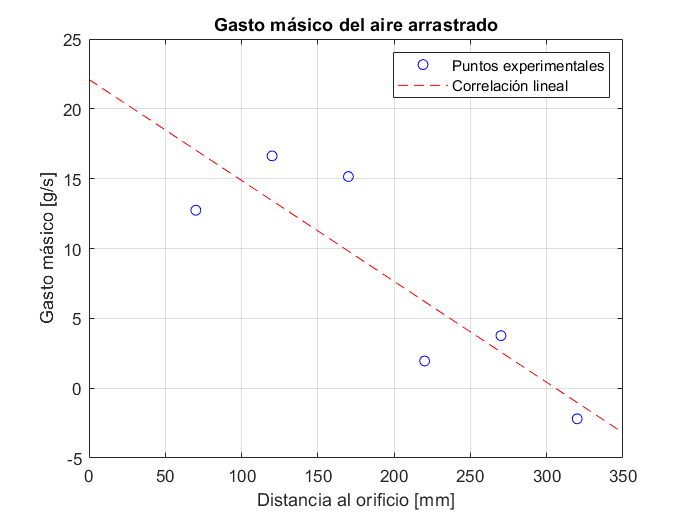

Zfe=[z1 z2 z3 z4 z5 z6].*1000;
figure(10)
plot(Zfe,Gfe,'o','color','blu')

ppfe=polyfit(Zfe,Gfe,1);
PPfe=poly2sym(ppfe);
hold on
fplot(PPfe,'--','color','red')
title('Gasto másico del aire arrastrado')
xlabel('Distancia al orificio [mm]')
ylabel('Gasto másico [g/s]')
legend('Puntos experimentales','Correlación lineal','Location','northeast')
xlim([0 350])
ylim([-5 25])
hold off
grid on

# Práctica 3. Pérdidas de carga

## **Datos**

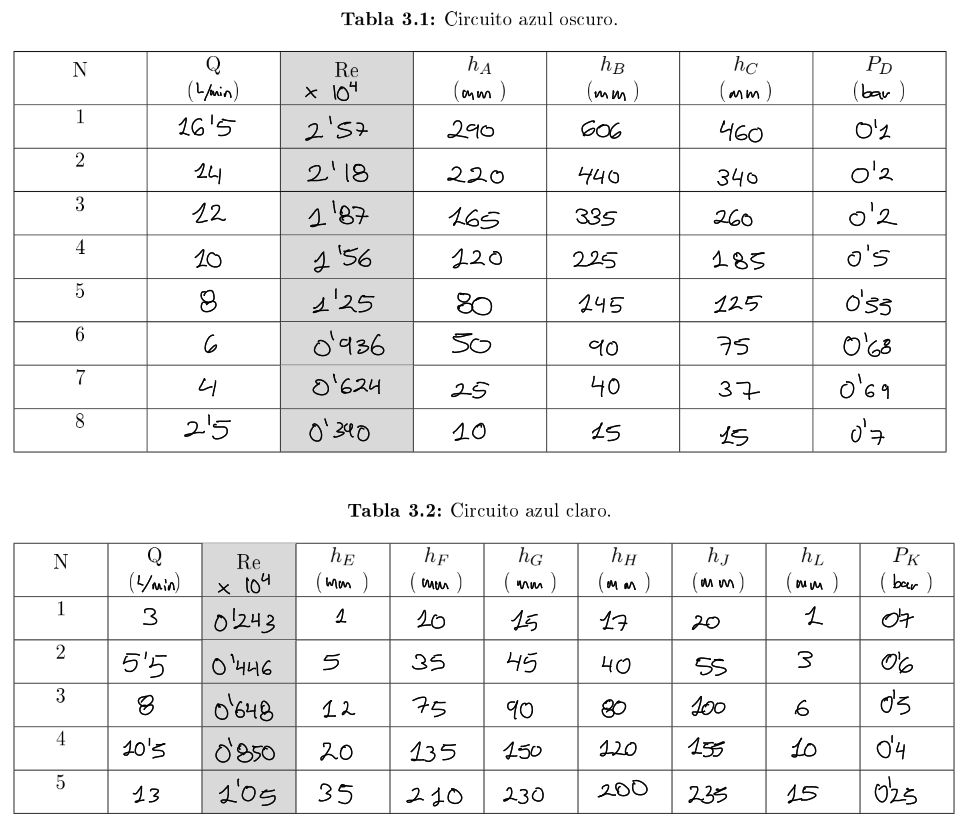

**Circuito azul oscuro**

Qao=[16.5 14 12 10 8 6 4 2.5].*((10^-3)./(60));%[m^3/s]
hA=[290 220 165 120 80 50 25 10].*(10^-3);%[m]
hB=[606 440 335 225 145 90 40 15].*(10^-3);%[m]
hC=[460 340 260 185 125 75 37 15].*(10^-3);%[m]
PD=[0.1 0.2 0.2 0.5 0.55 0.68 0.69 0.7].*(10^5);%[Pa]

%Tramo de tubería recta (A)
dA=13.6*(10^-3);%[m] diámetro de la tubería
LA=0.9144;%[m] longitud de la tubería

%Inglete (B)

%Codo regular 90º (C)

%Válvula de la compuerta (D)

**Circuito azul claro**

Qac=[3 5.5 8 10.5 13].*((10^-3)./(60));%[m^3/s]
hE=[1 5 12 20 35].*(10^-3);%[m]
hF=[10 35 75 135 210].*(10^-3);%[m]
hG=[15 45 90 150 230].*(10^-3);%[m]
hH=[17 40 80 120 200].*(10^-3);%[m]
hJ=[20 55 100 155 235].*(10^-3);%[m]
hL=[1 3 6 10 15].*(10^-3);%[m]
PK=[0.7 0.6 0.5 0.4 0.25].*(10^5);%[Pa]

%Ensanchamiento de la sección (E)
dE1=13.6*(10^-3);%[m] diámetro inicial
dE2=26.2*(10^-3);%[m] diámetro final

%Contracción de sección (F)
dF1=26.2*(10^-3);%[m] diámetro inicial 
dF2=13.6*(10^-3);%[m] diámetro final

%Curva de radio corto (G)
dG=50*(10^-3);%[m] diámetro de la curva

%Curva de radio medio (H)
dH=100*(10^-3);%[m] diámetro de la curva

%Curva de radio largo (J)
dJ=150*(10^-3);%[m] diámetro de la curva

%Tramo recto de tubería (L)
dL=26.2*(10^-3);%[m] diámetro 
LL=0.9144;%[m] longitud de la tubería 

%Válvula de bola (K)

**Cálculo del número de Reynolds **


$$\textrm{Re}=\frac{4\rho Q}{\pi \mu D}$$


rho=1000;%[kg/m^3] densidad del agua
mu=10^-3;%[Pa*s] viscosidad absoluta del agua
Re_ao=(4.*rho.*Qao)./(pi().*mu.*dA)%[-]

Re_ao = 1.0e+04 *

    2.5746    2.1845    1.8724    1.5603    1.2483    0.9362    0.6241    0.3901


Re_ac=(4.*rho.*Qac)./(pi().*mu.*dL)%[-]

Re_ac = 1.0e+04 *

    0.2430    0.4455    0.6480    0.8504    1.0529


**Cálculo para los factores de fricción para los tramos horizontales **


$$f=\Delta h_P \frac{1}{\frac{L}{D}}\frac{1}{\frac{v^2 }{2g}}=\Delta h_P \frac{\pi^2 }{8}\frac{{\textrm{gD}}^5 }{{\textrm{LQ}}^2 }$$


g=9.81;%[m/s^2] aceleración de la gravedad
fao=hA.*((pi()^2)./8).*((g.*(dA.^5))./(LA.*(Qao.^2)))%[-]

fao =     0.0236    0.0249    0.0254    0.0266    0.0277    0.0308    0.0346    0.0355


fac=hL.*((pi()^2)./8).*((g.*(dL.^5))./(LL.*(Qac.^2)))%[-]

fac =     0.0654    0.0583    0.0551    0.0534    0.0522


**Representación gráfica de cada circuito f-Re**

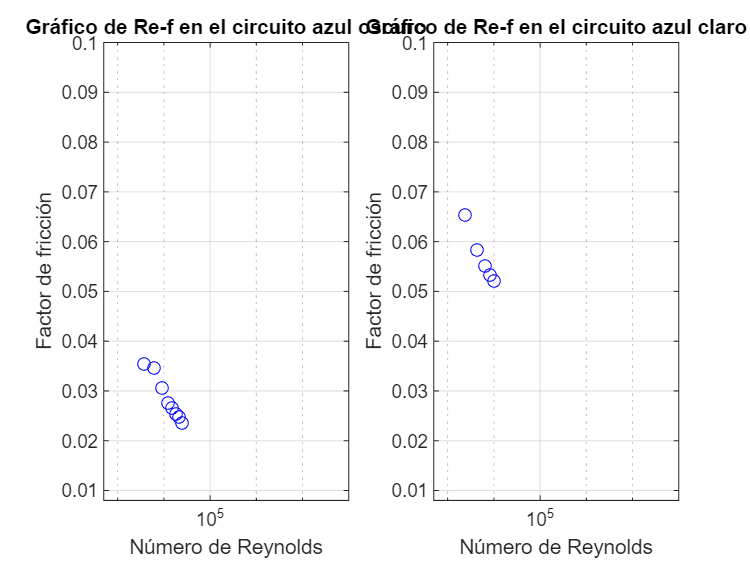

%Re-f_ao
figure(5)
subplot(1,2,1);
semilogx(Re_ao,fao,'o','color','blue')
xlabel('Número de Reynolds')
ylabel('Factor de fricción')
title('Gráfico de Re-f en el circuito azul oscuro')
xlim([5*10^2 10^8])
ylim([0.008 0.1])
grid on
%Re-f_ac
subplot(1,2,2)
semilogx(Re_ac,fac,'o','color','blue')
xlabel('Número de Reynolds')
ylabel('Factor de fricción')
title('Gráfico de Re-f en el circuito azul claro')
xlim([5*10^2 10^8])
ylim([0.008 0.1])
grid on

**Diagrama de Moody (f-Re)**

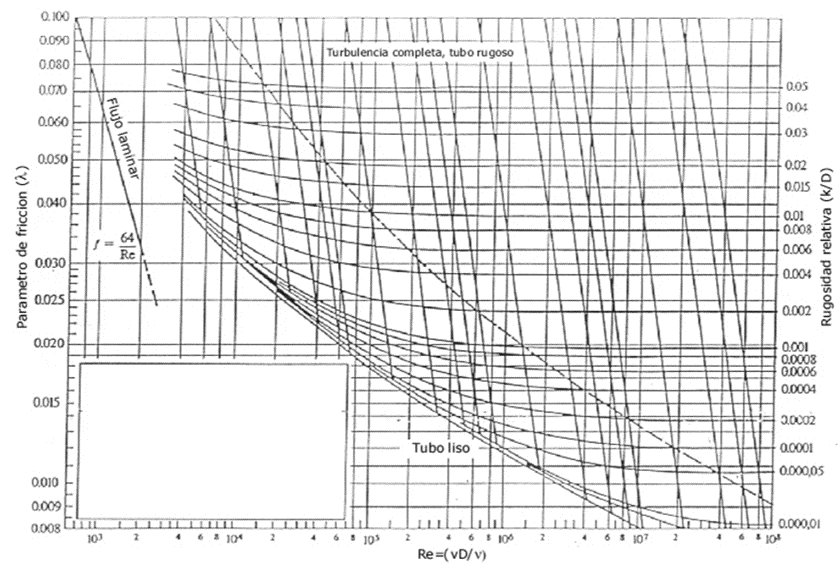

**Cáluclo de los coeficientes K de pérdidas secundarias **


$$\begin{array}{l}
K=\frac{D_j^4 }{D_1^4 }-\frac{D_j^4 }{D_2^4 }+\frac{g\pi^2 \Delta {h\;D}_j^4 }{8Q^2 }\;\;\textrm{Ensanchamiento}\;j=1,\textrm{contracción}\;j=2\;\;\;\;y\\
\;\sin \;\textrm{cambio}\;\textrm{de}\;\textrm{sección}\;D_1 =D_2 \;,\;j=1=2
\end{array}$$
 

%Las tomas de todas las pérdidas secundarias, excepto válvulas,
%ensanchamiento y contracción, llevan asociado una pérdida de rozamiento
%igual a la del tubo recto estrecho.Por tanto, a todas ellas se debe restar 
% la pérdida asociada a la diferencia de valor de las tomas 3 y 4 (A) para el 
% mismo caudal de cálculo.

%Tubería azul oscuro

%Tramo de tubería recta
K_A=(g.*(pi().^2).*hA.*(dA^4))./(8.*(Qao.^2))

K_A =     1.5877    1.6730    1.7079    1.7886    1.8631    2.0702    2.3289    2.3848



%Inglete
K_B=(g.*(pi().^2).*hB.*(dA^4))./(8.*(Qao.^2))-K_A

K_B =     1.7300    1.6730    1.7596    1.5650    1.5138    1.6561    1.3974    1.1924



%Codo angular de 90º
K_C=(g.*(pi().^2).*hC.*(dA^4))./(8.*(Qao.^2))-K_A

K_C =     0.9307    0.9126    0.9833    0.9688    1.0480    1.0351    1.1179    1.1924



%Tubería azul claro

%Ensanchamiento de la sección (E)
K_E=1-((dE1.^4)./(dE2.^4))+(g.*(pi().^2).*hE.*(dE1^4))./(8.*(Qac.^2))

K_E =     1.0930    1.1738    1.2069    1.1978    1.2361



%Contracción de sección (F)
K_F=-1+((dF2.^4)./(dF1.^4))+(g.*(pi().^2).*hF.*(dF2^4))./(8.*(Qac.^2))

K_F =     0.7287    0.7972    0.8193    0.8977    0.9247



%Tramo recto de tubería (L)
K_L=(g.*(pi().^2).*hL.*(dL^4))./(8.*(Qac.^2))

K_L =     2.2811    2.0360    1.9247    1.8621    1.8222



%Curva de radio corto (G)
K_G=(g.*(pi().^2).*hG.*(dG^4))./(8.*(Qac.^2))-K_L

K_G =   451.5665  403.0511  381.0092  368.6257  368.7753



%Curva de radio medio (H)
K_H=(g.*(pi().^2).*hH.*(dH^4))./(8.*(Qac.^2))-K_L

K_H = 1.0e+03 *

    8.2275    5.7592    5.4442    4.7404    5.1543



%Curva de radio largo (J)
K_J=(g.*(pi().^2).*hJ.*(dJ^4))./(8.*(Qac.^2))-K_L

K_J = 1.0e+04 *

    4.9013    4.0102    3.4462    3.1008    3.0669


**Representación gráfica de cada tramo Re-K**

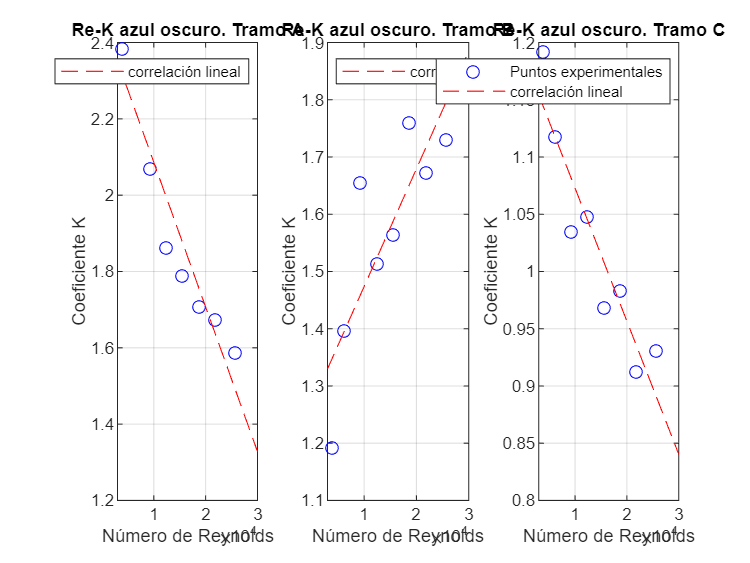

%Para el tramo A
figure(6)
subplot(1,3,1);
plot(Re_ao,K_A,'o','color','blue')
xlabel('Número de Reynolds')
ylabel('Coeficiente K')
title('Re-K azul oscuro. Tramo A')
xlim([3000 30000])
ylim([0 5])
t1=polyfit(Re_ao,K_A,1); %correlación lineal
T1=poly2sym(t1);
hold on
fplot(T1,'--','color','red')
hold off
legend('','correlación lineal')
grid on

%Para el tramo B
subplot(1,3,2);
plot(Re_ao,K_B,'o','color','blue')
xlabel('Número de Reynolds')
ylabel('Coeficiente K')
title('Re-K azul oscuro. Tramo B')
xlim([3000 30000])
ylim([0 5])
t2=polyfit(Re_ao,K_B,1);%correlación lineal
T2=poly2sym(t2);
hold on
fplot(T2,'--','color','red')
hold off
legend('','correlación lineal','Location','northwest')
grid on

%Para el tramo C
subplot(1,3,3)
plot(Re_ao,K_C,'o','color','blue')
xlabel('Número de Reynolds')
ylabel('Coeficiente K')
title('Re-K azul oscuro. Tramo C')
xlim([3000 30000])
ylim([0 5])
t3=polyfit(Re_ao,K_C,1);%correlación lineal
T3=poly2sym(t3);
hold on
fplot(T3,'--','color','red')
hold off
legend('Puntos experimentales','correlación lineal')
grid on

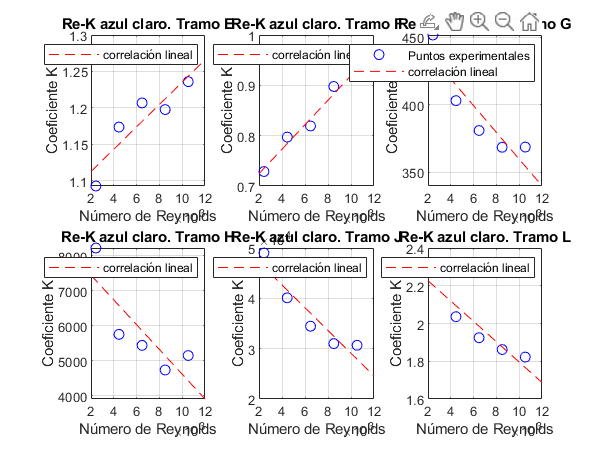


figure(7)
%Para el tramo E
subplot(2,3,1);
plot(Re_ac,K_E,'o','color','blue')
xlabel('Número de Reynolds')
ylabel('Coeficiente K')
title('Re-K azul claro. Tramo E')
ax = gca;
ax.XAxis.Exponent = 3;
xlim([2*10^3 12*10^3])
ylim([0 5])
t4=polyfit(Re_ac,K_E,1);%correlación lineal
T4=poly2sym(t4);
hold on
fplot(T4,'--','color','red')
hold off
legend('','correlación lineal')
grid on

%Para el tramo F
subplot(2,3,2);
plot(Re_ac,K_F,'o','color','blue')
xlabel('Número de Reynolds')
ylabel('Coeficiente K')
title('Re-K azul claro. Tramo F')
ax = gca;
ax.XAxis.Exponent = 3;
xlim([2*10^3 12*10^3])
ylim([0 5])
t5=polyfit(Re_ac,K_F,1);%correlación lineal
T5=poly2sym(t5);
hold on
fplot(T5,'--','color','red')
hold off
legend('','correlación lineal')
grid on

%Para el tramo G
subplot(2,3,3);
plot(Re_ac,K_G,'o','color','blue')
xlabel('Número de Reynolds')
ylabel('Coeficiente K')
title('Re-K azul claro. Tramo G')
ax = gca;
ax.XAxis.Exponent = 3;
xlim([2*10^3 12*10^3])
t6=polyfit(Re_ac,K_G,1);%correlación lineal
T6=poly2sym(t6);
hold on
fplot(T6,'--','color','red')
hold off
legend('Puntos experimentales','correlación lineal')
grid on

%Para el tramo H
subplot(2,3,4);
plot(Re_ac,K_H,'o','color','blue')
xlabel('Número de Reynolds')
ylabel('Coeficiente K')
title('Re-K azul claro. Tramo H')
ax = gca;
ax.XAxis.Exponent = 3;
xlim([2*10^3 12*10^3])
t7=polyfit(Re_ac,K_H,1);%correlación lineal
T7=poly2sym(t7);
hold on
fplot(T7,'--','color','red')
hold off
legend('','correlación lineal')
grid on

%Para el tramo J
subplot(2,3,5);
plot(Re_ac,K_J,'o','color','blue')
xlabel('Número de Reynolds')
ylabel('Coeficiente K')
title('Re-K azul claro. Tramo J')
ax = gca;
ax.XAxis.Exponent = 3;
xlim([2*10^3 12*10^3])
t8=polyfit(Re_ac,K_J,1);%correlación lineal
T8=poly2sym(t8);
hold on
fplot(T8,'--','color','red')
hold off
legend('','correlación lineal')
grid on

%Para el tramo L
subplot(2,3,6)
plot(Re_ac,K_L,'o','color','blue')
xlabel('Número de Reynolds')
ylabel('Coeficiente K')
title('Re-K azul claro. Tramo L')
ax = gca;
ax.XAxis.Exponent = 3;
xlim([2*10^3 12*10^3])
t9=polyfit(Re_ac,K_L,1);%correlación lineal
T9=poly2sym(t9);
hold on
fplot(T9,'--','color','red')
hold off
legend('','correlación lineal')
grid on